# **Effective Solar House Design**

*Authors: *Drew Pang and Kelly Stellmacher

Traditional houses attempt to seperate the temperature controled air from outside air

## **Question:**

**Prompts:**

- What is/are the motivating question(s)? 

- What type of question is this (explanatory, predictive, or design)?

- Why is this an important or interesting question?

- What will we learn by asking this question?

Type of question: Design

What thickness of insulation in a solar house in Columbus, Ohio in Winter would maintain i a minimum nternal temperature over time?

This question is interesting because it examines the viability of a house heated without any artificial energy usage, therefore being much more environmentally sustainable than a house heated by electricity or natural gas. 

## **Model:**

**Prompts:**

- How are you going to answer your question? 

- What assumptions are you making? Are these good or bad assumptions?

- How did you develop and refine your model?

- What additional representations of your model help to communicate it to your reader (e.g., equations, stock and flow diagrams)? 

- How did you set the parameters of your model?

- How did you verify your model?

- Optional: If you had more time, what plan would you use to validate your model?

To answer our question, we devdloped the following scematic diagram:

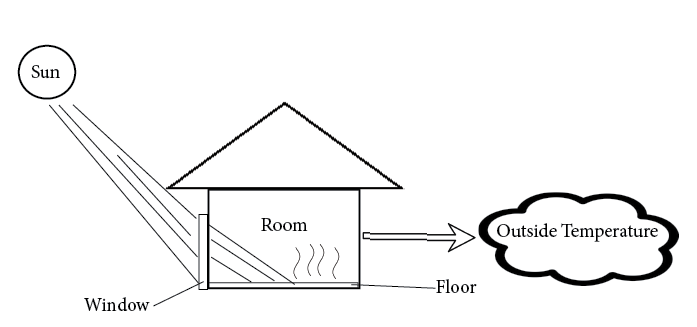

Where energy radiates from the sun, through the window of the house, into the floor, and then conducts from the floor into the air contained in the house. The energy then leaves the house via convecting through the walls. 

Using the scematic, we developed the following stock and flow diagram:

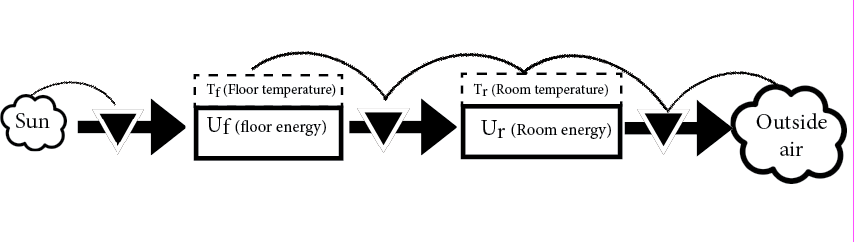

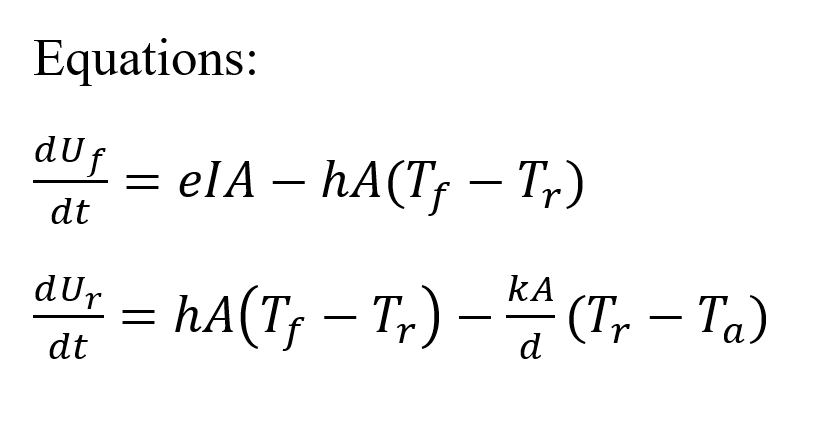

Parameters: 

- Tf(1) = 293; floor starting temperature (K)

- Tr(1) = 293; house int starting temperature (K)

- Ta = 263.56; external temperature (K)

- w = 10; sidelength of house (m)

- wt = .30; thickness of walls (m)

- wf = .05715; thickness of floor (m)

- I = 170.14; incident solar radiation (w/m^2)

- e = 0.885; emmisivity of floor (oak) (j/m^2)

- h_a = 0.026; thermal conductivity of air (w/m)

- h_w = 0.05; thermal conductivity of walls (insulation) (w/m)

- h_f = 0.170; thermal conductivity of floor (wood) (w/m)

- s_f = 1850; specific heat of floor(j/kg C)

- s_a = 1005; specific heat of air (j/kg C)

- d = 1.293; density of air (kg/m^3)

- d_f = 745; density of floor (kg/m^3)

Assumptions for our model inlcude:

- The structural integrity of the house will not be jepordized based on the material the walls are composed of. 

- The roof is made of the same material as the walls. 

- The aperture of the window will remain constant.

- The Sun zenith angle remains the same.

- The house is empty: no people or furniture is present to alter energy content of the room

- There is nothing obstructing the sunlight from reaching the house. 

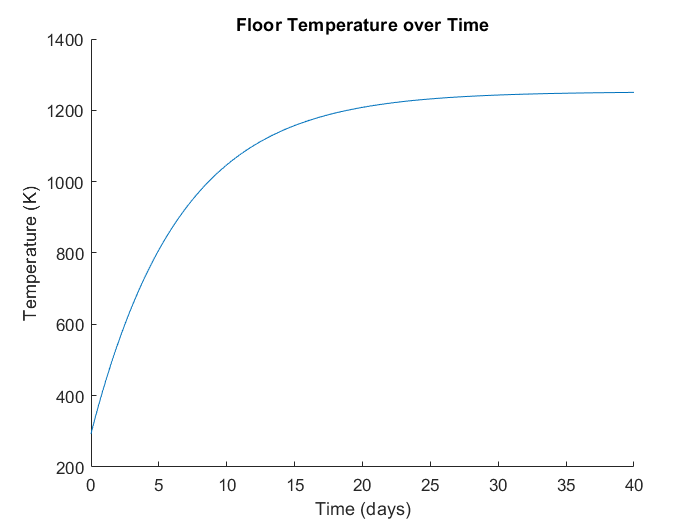

[T,D] = solar_house_ode45();
figure(1);
clf; hold on;
title('Floor Temperature over Time');
plot(T/(24*3600),D(:,1));
xlabel('Time (days)')
ylabel('Temperature (K)')

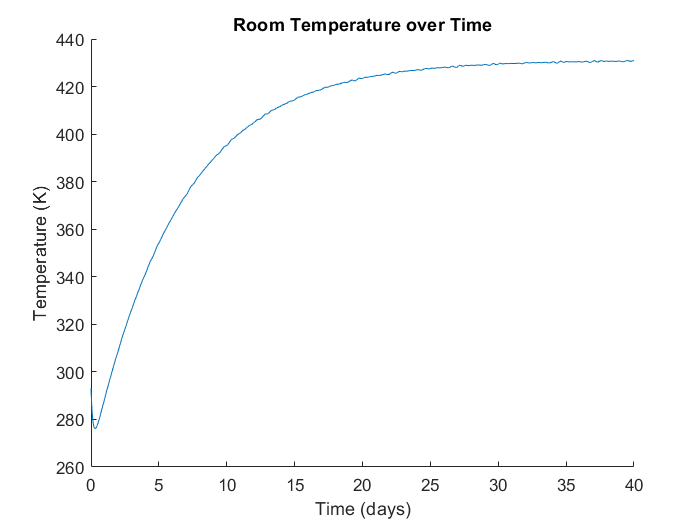


figure(2)
clf; hold on;
title('Room Temperature over Time');
plot(T/(24*3600),D(:,2));
xlabel('Time (days)')
ylabel('Temperature (K)')

## **Results:**

**Prompts:**

- What results did your model generate?

- Are there any key points of information in your results that  are most important or that will be most useful in your interpretation?  (Label key elements of your results figures.) 

## **Interpretation:** 

**Prompts:**

- How do the results answer the question?

- Do you think the answer is a good one? 

- What are the limitations of your model? 

- If you were going to continue developing your model, what next steps might you take? 